% Clear command window, workspace variables, and close all figures
clear; clc; close all;

% Set the path to the folder containing the layer data
layerfolder = '../VirtualSpeciesGeneration/data/layers/';

% Read in the layer data from the specified folder
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 2.807876 seconds.



% Generate initial point for niche generation using a virtual species method
InfoInitialPoint = InitialPoint(Dimensions,'harmonic');

Elapsed time is 12.036874 seconds.


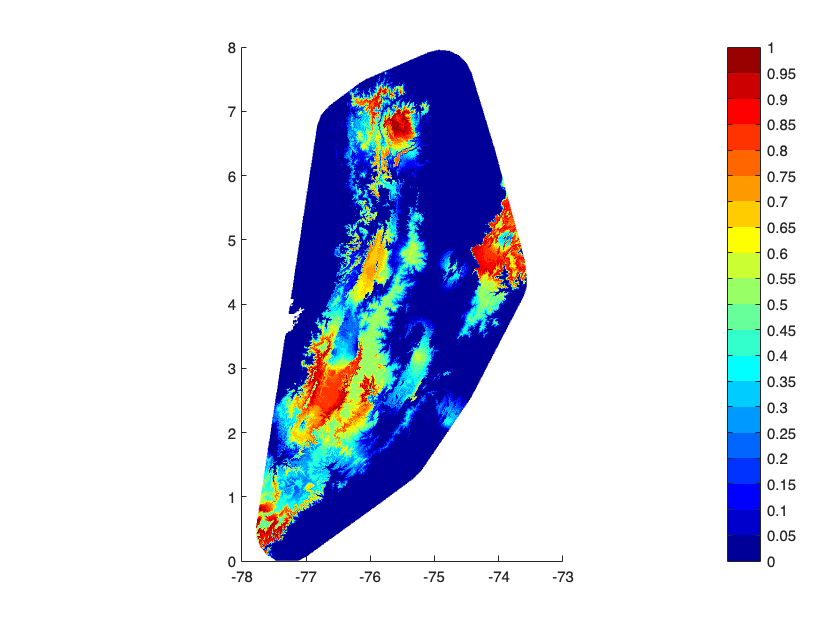

Elapsed time is 1.728971 seconds.



% Generate the niche map using niche generation algorithm with the initial point
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

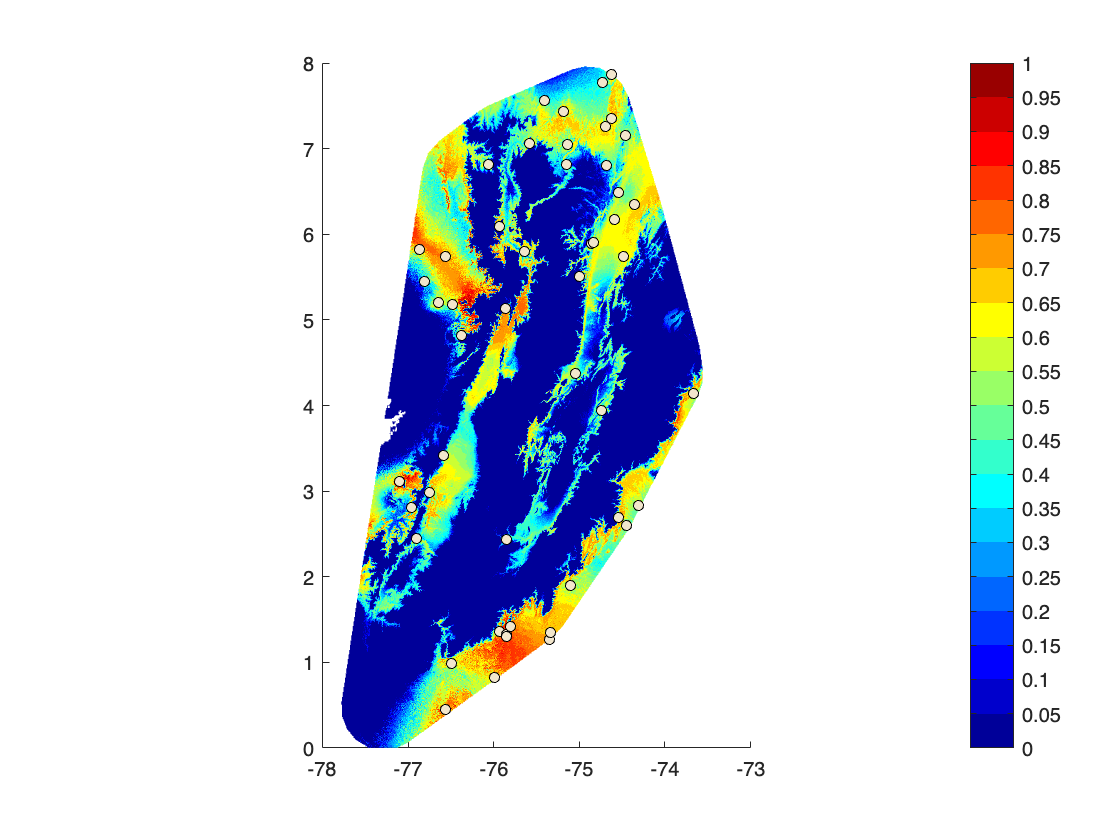

% Sample virtual species using the generated niche map
T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -1, true, 'GenSP', true, true);